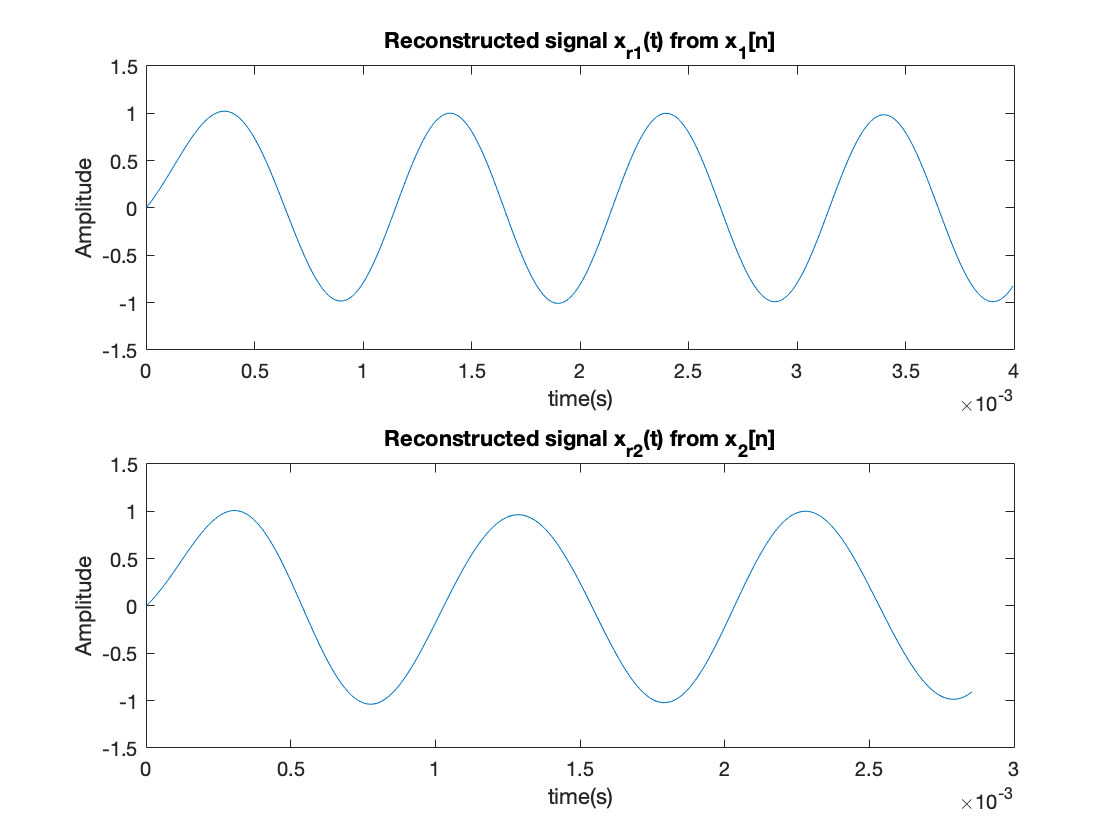

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : Reconstruction of signal
%----------------------------------------------------------------------
close all;
clc;

%sampling the signal
Fs1 = 2500;
T1 = 1/Fs1;
Fs2 = 3500;
T2 = 1/Fs2;
L = 1000; %no of samples
xr1 = zeros(1, 1000); %reconstruction matrix
time1 = [0:L-1]*T1;

t1 = 0:1/Fs1:ncycle/1000;
t2 = 0:1/Fs2:ncycle/1000;
L1 = length(t1);
L2 = length(t2);
x1 = cos(2000.*pi.*t1);
x2 = cos(2000.*pi.*t2);

%reconstruction of signal for sampled signal with Fs = 2500
%It is linear sum of sinc signal
n1 = 1:L1;
for i = 1:1000
    tr1 = (i-1)*T1/100;
    h1 = sinc((tr1-n1.*T1)./T1);
    xr1(i) = x1*h1';
end
   
hold on
subplot(2,1,1);
plot(time1, xr1);
xlabel('time(s)');
ylabel('Amplitude');
title('Reconstructed signal x_{r1}(t) from x_1[n]');

xr2 = zeros(1, 1000);
time2 = [0:L-1]*T2;

%reconstruction of signal for sampled signal with Fs = 3500
%It is linear sum of sinc signal
n2 = 1:L2;
for i = 1:1000
    tr2 = (i-1)*T2/100;
    h2 = sinc((tr2-n2.*T2)./T2);
    xr2(i) = x2*h2';
end
   
hold on
subplot(2,1,2);
plot(time2, xr2);
xlabel('time(s)');
ylabel('Amplitude');
title('Reconstructed signal x_{r2}(t) from x_2[n]');